# Constraint and Mapping Example

This example shows 3 things:

- Mapping input variables to a new input space because relationship from x to y is so nonlinear that fitting a lookup table is difficult. Large nonlinear changes are not well captured by regularizeNd or regularizeNdMatrices. 

- Using a semilog space of the output, `log10(y)`. When the output changes so rapidly that it jumps several orders of magnitude, you may want to consider fitting `log10` of the output, `y`. The other reason is that the input to the output may be polynomial like. If it is polynomial like, a polynomial in log space is smoother and changes slower.

- Inequality and bounded constraints. Handling constraints are easy using regularizeNdMatrices with `lsqlin` or `lsqConstrainedAlternative`. Monotonic constraints and bounded constraints are easily handled in this example. Equality constraints are possible as well but are not discussed here.

## Load and Clean the Data

For what we are going to do, we need to discard $y\le 0$.

clc; clear; close all;
load('Data for Constraint and Mapping Example.mat','x','y');
index = y<=0;
x(index)=[];
y(index)=[];

## Examine the Data

`x` to `y` is highly nonlinear. Specifically note the sudden and large changes in `y` at` x=6` and `x=6.45`.

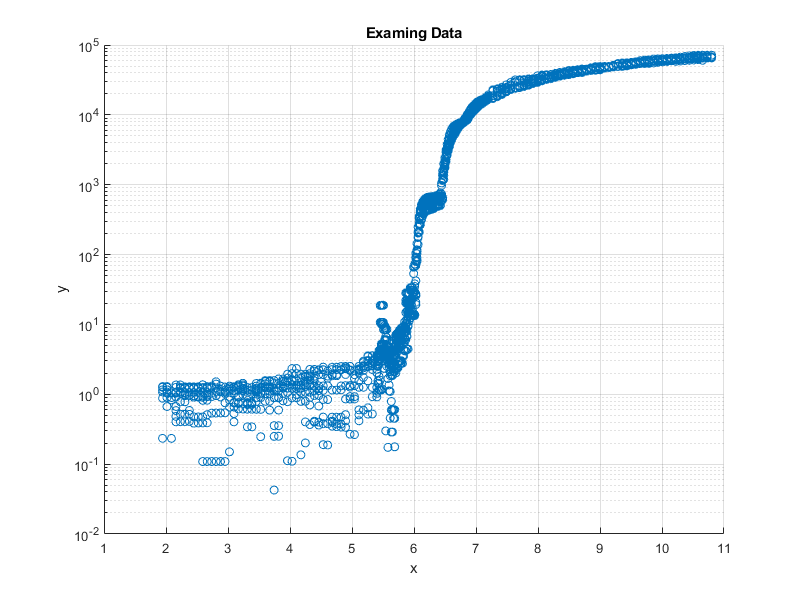

screenSize = get(groot,'ScreenSize');
figurePosition = screenSize(3:4)*0.1;
% figureSize = screenSize(3:4)*0.8;
figureSize = [800 600];
figurePositionAndSize = [figurePosition figureSize];
figure('Position',figurePositionAndSize)
scatter(x,y)
xlabel('x')
ylabel('y')
set(gca,'yscale','log')
grid on;
title('Examing Data')

## Map x to a New Space for a Smoother Map

The mapping is created manually. See the video "Mapping_Example.mp4" in the same directory you found this file. Also, the graph used in the video is "Mapping_Example.fig".

The idea is to make all sections of the data the same slope, $\frac{\Delta y}{\Delta x}$, or at least a similar slope. See the video on how I get a rough idea of the sections of the data. `pchip` interpolation is used because it is the smoothest interpolant that guarantees monotonic interpolation (aka no oscillations) in the mapping; a 1 to 1 mapping (1 x point maps to only 1 xNew point) is desired/required. The `akima` interpolation method does not always give a monotonic interpolation.

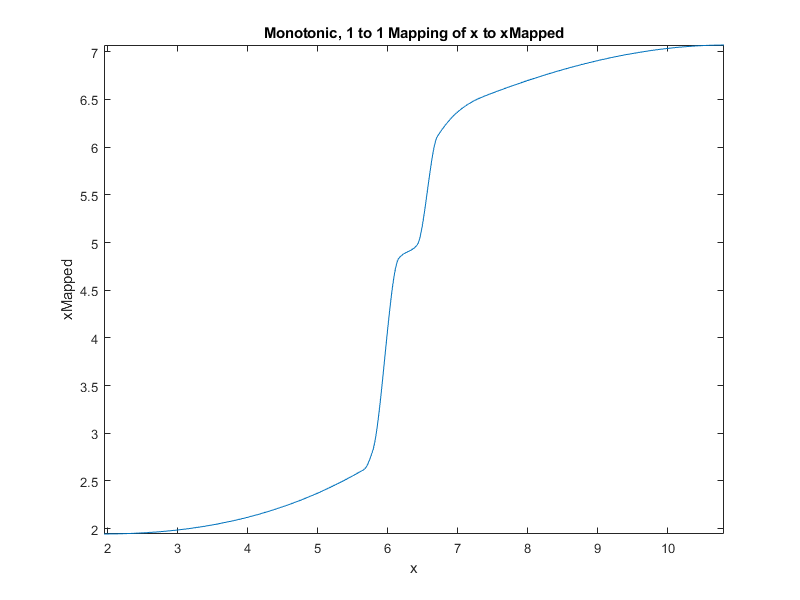

load('Data for Constraint and Mapping Example','xValues','yValues')
desiredSlope = 1; % arbitrarily chosen
xDifference = diff(xValues);

% calculate the semilog slope
semilogSlope = diff(log10(yValues))./xDifference;

% scale slope in each section to the desired slope
xMapping = nan(size(xValues));
xMapping(1) = min(x);
for iX = 2:length(xMapping)
    xMapping(iX) = xMapping(iX-1) + semilogSlope(iX-1)./desiredSlope.*xDifference(iX-1);
end

mapping = griddedInterpolant(xValues, xMapping,'pchip','linear');

figure('Position',figurePositionAndSize)
fplot(@(x) mapping(x),[min(x), max(x)])
xlabel('x')
ylabel('xMapped')
title('Monotonic, 1 to 1 Mapping of x to xMapped')

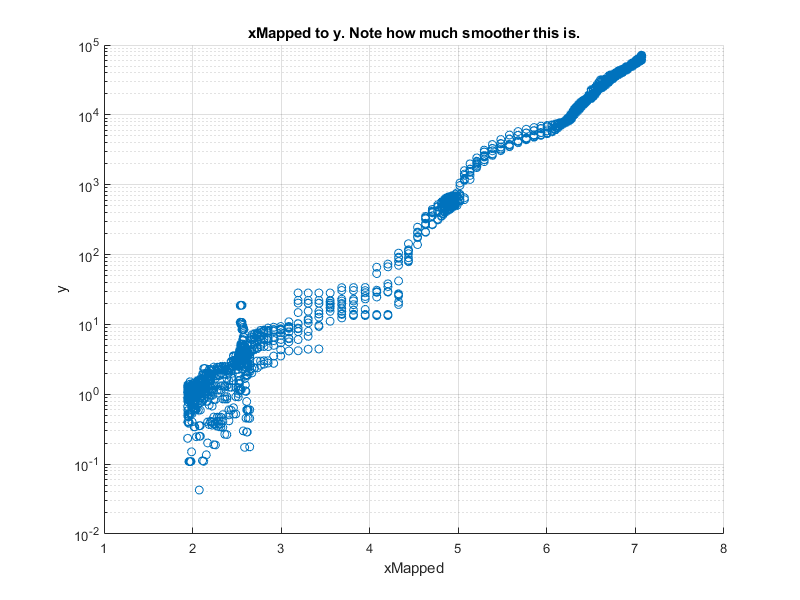


% plot new input to output
xMapped = mapping(x);
figure('Position',figurePositionAndSize)
scatter(xMapped, y)
xlabel('xMapped')
ylabel('y')
set(gca,'yscale','log')
grid on;
title('xMapped to y. Note how much smoother this is.')

## Call regularizeNd Matrices

Setup an `xGrid` and then map it to the new `xMapped` space. The fitting will be done in the mapped space. 

`y` is converted to `log10` space because `log10(y)` is smoother than `y`.

Call regularizeNdMatrices. Get the fidelity matrix, `Cfidelity,` and the regularization matrix, `Lregularization` (in other cases, `Lregularization is "`matrices" if there is more than one input).

Combine the fidelity matrix, `Cfidelity,` and the regularization matrix, `Lregularization,` into one composite matrix, `C`.

Create the corresponding vector to `C, d.`

Note that the matrices correspond to the objective function:


$$J =\frac{1}{2}||C*yGrid-d||_2^2$$


xGrid = {linspace(min(x),max(x),1000)};
xGridMapped = {mapping(xGrid{:})};
yLog10 = log10(y);
smoothness = 1e-3;

[Cfidelity, Lregularization] = regularizeNdMatrices(xMapped, xGridMapped, smoothness);
C = vertcat(Cfidelity,Lregularization{:}); % note this line of code works even if Lregularization has more than one cell

dFidelity = yLog10;
dRegularization = zeros(size(C,1)-size(Cfidelity,1),1);
d = vertcat(dFidelity, dRegularization);


## Setup the Constraint Matrix

In this case, the desired constraint is that the lookup table, `yGrid`, is monotonically increasing. Also, the bound is that no value in the table is less than 0.

The constraints are formed as inequalities like this:


$$A*yGrid\leq b$$


    % Monotonic constraint matrix
    nGridPoints = length(xGrid{1});
    Amonotonic = sparse(nGridPoints,nGridPoints);
    Amonotonic = spdiags(ones(nGridPoints-1,1),-1,Amonotonic);
    Amonotonic = spdiags(-ones(nGridPoints,1),0,Amonotonic);
    Amonotonic = Amonotonic(2:end,:);
    
    % monotonic constraint vector
    bMonotonic = sparse(size(Amonotonic,1),1);
    
    % Bound constraint matrix
    Abound = sparse(nGridPoints,nGridPoints);
    Abound = spdiags(-ones(nGridPoints,1),0,Abound);
    
    % bound constraint vector
    bBound = sparse(size(Abound,1),1);
    
    % Composite constraint matrix and vector
    A = vertcat(Amonotonic, Abound);
    b = vertcat(bMonotonic, bBound);

## Solve for the lookup table Using `lsqConstrainedAlternative`

Using the provided solver `lsqConstrainedAlternative to` find the lookup table `yGrid1`.

Create a funciton for use in evaluation.

    tic;
    yLog10Grid1 = lsqConstrainedAlternative(C,d,A,b);
    toc;

Elapsed time is 0.511328 seconds.


    yLog10GridFunction1 = griddedInterpolant(xGridMapped, yLog10Grid1,'linear');
    yFunction1 = @(x) 10.^yLog10GridFunction1(mapping(x));

## Solve for  lookup table Using `lsqlin`

Using the `lsqlin` solver has advantages. It has some more flexibility too but Optimization Toolbox is required`. lsqlin `can handle equality constraint but it is not shown here. In some cases `lsqlin `won't converge when `lsqConstrainedAlternative` does.

    % make sure lsqlin exists. If it doesn't warn the user they don't have the optimization toolbox
    if exist('lsqlin','file')
        tic;
        options = optimoptions('lsqlin', 'Display', 'iter-detailed');
        yLog10Grid2 = lsqlin(C,d,A,b,[],[],[],[],[],options);
        toc;
    else
        warning('Optimization Toolbox is not installed because lsqlin could not be located. Use lsqConstrainedAlternative or another provided linear solver.')
    end

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -4.259316e+03   0.000000e+00   8.353870e+01     1.752664e-03  
    1   -9.718075e+03   4.396037e-03   4.277259e+00     7.406805e-04  
    2   -1.035597e+04   0.000000e+00   1.512081e+00     1.935858e-04  
    3   -1.040519e+04   0.000000e+00   1.525785e+00     4.552291e-05  
    4   -1.041934e+04   0.000000e+00   7.853620e-01     6.681722e-06  
    5   -1.042262e+04   0.000000e+00   1.155745e+00     9.884776e-07  
    6   -1.042105e+04   0.000000e+00   2.061875e+00     2.133177e-07  
    7   -1.042249e+04   0.000000e+00   1.017399e+00     6.894161e-08  
    8   -1.042318e+04   0.000000e+00   9.999846e-01     4.439170e-09  

Optimization completed: The relative dual feasibility, 8.809986e-17,
is less than options.OptimalityTolerance = 1

Elapsed time is 0.112131 seconds.


    
    yLog10GridFunction2 = griddedInterpolant(xGridMapped, yLog10Grid2,'linear');
    yFunction2 = @(x) 10.^yLog10GridFunction2(mapping(x));
    

## Plot the Results

The fitted lookup tables work great in both the `lsqConstrainedAlternative` and` lsqlin` cases. 

Note that both fits are monotonicly increasing and greater than 0.

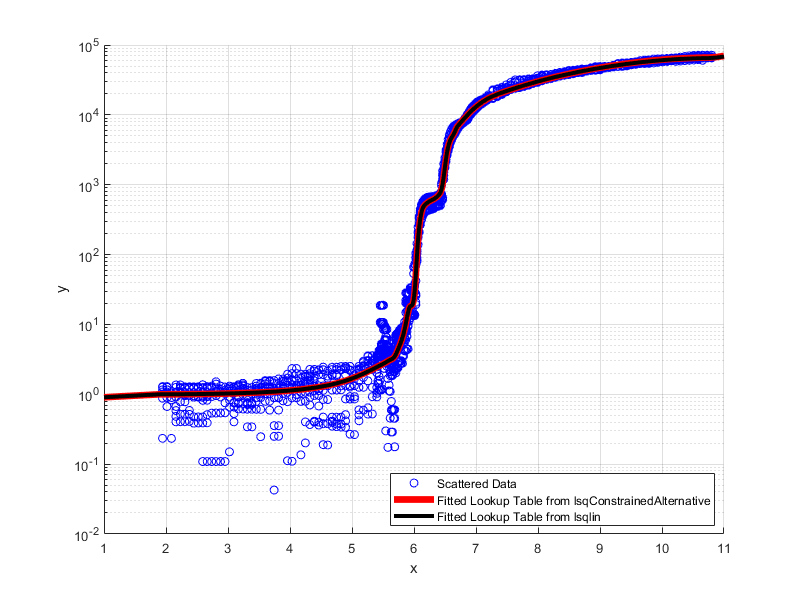

figure('Position',figurePositionAndSize)
scatter(x,y,'b');
hold all;
fplot(yFunction1,xlim,'r','linewidth',5);
fplot(yFunction2,xlim,'k','linewidth',3);
xlabel('x')
ylabel('y')
set(gca,'yscale','log')
grid on;
legend({'Scattered Data','Fitted Lookup Table from lsqConstrainedAlternative', 'Fitted Lookup Table from lsqlin'},'location','best')